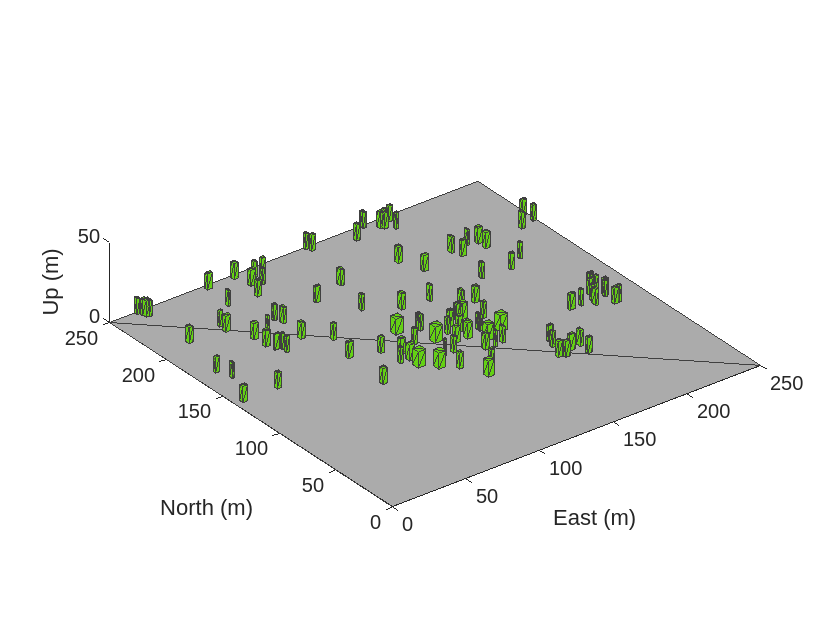

% Create the UAV scenario.
scene = uavScenario(UpdateRate=2,ReferenceLocation=[75 -46 0]);

% Add a ground plane.
color.Gray = 0.651*ones(1,3);
color.Green = [0.3922 0.8314 0.0745];
color.Red = [1 0 0];
addMesh(scene,"polygon",{[0 0; 250 0; 250 250; 0 250],[-4 0]},color.Gray)

% load the data
load('../data/matlab_meshes/city_0.mat')

% Add sets of polygons as extruded meshes with varying heights from 10-30.
for i = 1:size(buildingCoords,2)
addMesh(scene,"polygon",{buildingCoords{i}(1:4,:),[0 10]},color.Green)
end

% Show the scenario.
show3D(scene);
xlim([0 250])
ylim([0 250])
zlim([0 50])

% Set up platform
plat = uavPlatform("UAV",scene,ReferenceFrame="NED",...
    InitialPosition=[100,100,5],InitialOrientation=eul2quat([0 0 0]));

% Set up platform mesh. Add a rotation to orient the mesh to the UAV body
% frame.
updateMesh(plat,"quadrotor",{10},color.Red,[0 0 0],eul2quat([0 0 pi]))

lidarmodel = uavLidarPointCloudGenerator(AzimuthResolution=0.3324099,...
    ElevationLimits=[-20 20],ElevationResolution=1.25,...
    MaxRange=90,UpdateRate=2,HasOrganizedOutput=true);

lidar = uavSensor("Lidar",plat,lidarmodel,MountingLocation=[0,0,-1]);

pt = pointCloud(nan(1,1,3));
setup(scene)
updateSensors(scene)

[isupdated,lidarSampleTime, pt] = read(lidar);

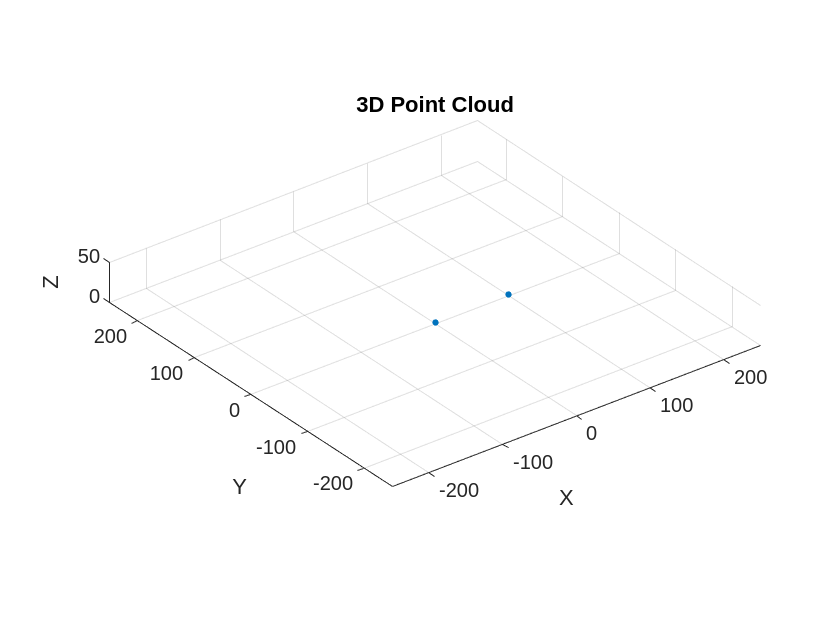

% Plotting the point cloud
figure;  % Create a new figure
colormap("jet")
scatterplot = scatter3([100 1 1],[1 1 1],[1 1 1],10,'filled');
scatterplot.XDataSource = "reshape(pt.Location(:,:,1),[],1)";
scatterplot.YDataSource = "reshape(pt.Location(:,:,2),[],1)";
scatterplot.ZDataSource = "reshape(pt.Location(:,:,3),[],1)";
scatterplot.CDataSource = "reshape(pt.Location(:,:,3),[],1) - min(reshape(pt.Location(:,:,3),[],1))";

xlabel('X');
ylabel('Y');
zlabel('Z');
title('3D Point Cloud');
grid on;  % Turn on the grid
axis equal;  % Equal axis scaling
xlim([-250 250])
ylim([-250 250])
zlim([0 50])